# Labolatorium 3 - Modulacja amplitudy, Demodulacja dla AM, DSB AM i SSB AM 

#### Opis Problemu:

Ćwiczenie polegało na:

-  Wygenerowaniu sygnałów $m_1 =A_m ∙\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_m t\right)$, m2-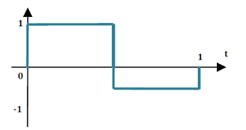, $m_3 =A_m ∙\sum_{i=1}^{10} \mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi it\right)$

-  Zmodulowaniu ich za pomocą moduluacji amplitudy w trzech waruantach: w wersji klasycznej AM, z wytłumioną falą nośną SC (subtracted carrier), i standardowo WC (with carrier).

- Przeanalizowaniu wykresów otrzymanych przebiegów, ich widm, obliczeniu pasma, mocy fali nośnej, wstęg bocznych i całego sygnału

- Zdemodulowaniu sygnałów, ocenieniu sprawności modulacji

- Wykonaniu modulacji SSB (single side band) za pomocą filtrów górno i dolnoprzepustowego.

#### Podstawy matematyczne:

Sygnał fali nośnej został zamodelowany równaniem c = Ac * cos(2*pi*fc*t)

Przy modulacji klasycznej AM sygnał zajmuje całe pasmo od najniższej częstotliwości modulowanej do częstotliwości nośnej. Przy modulacji dwuwstęgowej pasmo ma szerokość 2*W gdzie W to odległość od częstotliwości nośnej do wstęgi bocznej. Szerokość pasm sprawdzono za pomocą funkcji obw().

Moc sygnału obliczono jako rms(x)^2. Moc wstęg bocznych "Pwb" obliczono jako moc sygnału "Pam" pomniejszona o moc fali nośnej "Pc".

Sprawność modulacji obliczono jako n = Pwb/Pam

Demodulacja została przeprowadzona z wykożystaniem transformaty Hilberta do wyznaczenia obwiedni sygnału.

Detektor obwiedni 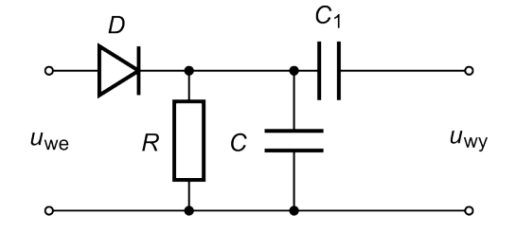poprawnie odwzoruje obwiednię sygnału jeżeli jego parametry spełnią zależność , gdzie fc - częstotliwość nośnej, W - najwyższa częstotliwość w paśmie. Aby nie doprowadzić do przemodulowania amplituda sygnału modulującego Am i amplituda nośnej muszą spełniać zależność .

#### Symulacje: 

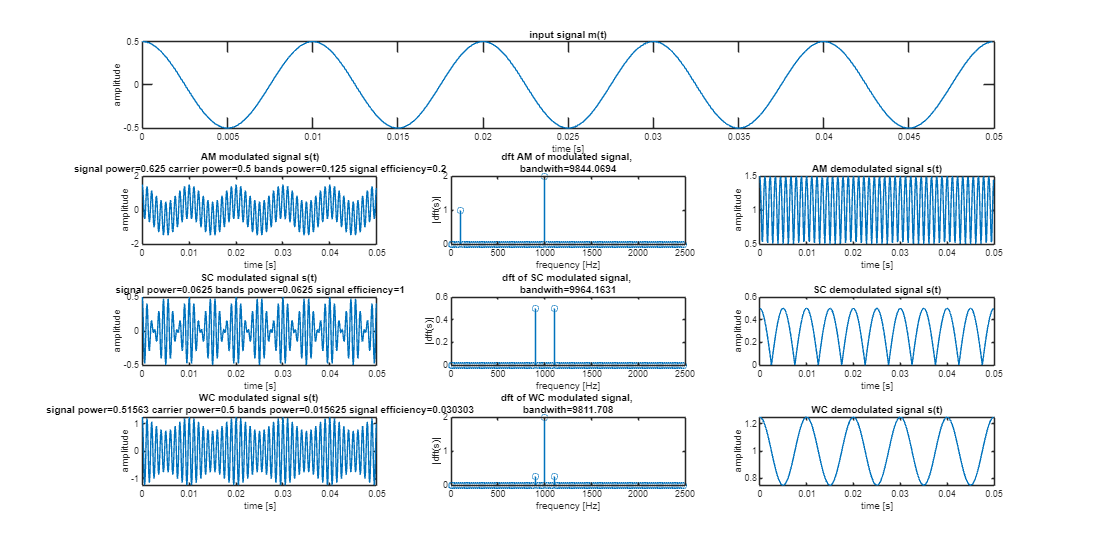

%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.5;
fm = 100;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m1-----------------------------


m1 = Am *cos(2*pi*fm*t);


calculate(c, fs, Am, Ac, t, m1)

#### Obserwacje:

Pierwszą symulacje przeprowadzono dla prostego sygnału sinusoidalnego. Kolejne wiersze pokazują różne metody modulacji. Obserwujemy że jedynie dla modulacji WC odwzorowany sygnał dostatecznie przypomina sygnał wejściowy.

Dft sygnałów przedstawiają kolejno, dwa prążki (sygnał modulujący oraz nośną) dla modulacji AM, Dwa prążki (wstęgi boczne) dla modulacji SC i trzy prążki (nośną oraz wstęgi boczne) dla modulacji WC.

Obserwujemy znaczną różnicę pomiędzy wykorzystanym pasmem dla sygnału z modulacją AM a pozostałymi dwoma.

Ustawiając amplitudę nośnej Ac mniejszą niż Am możemy zaobserwować efekt przemodulowania.

#### Wnioski:

Prostota Implementacji: AM jest stosunkowo prostą techniką modulacji do zrozumienia i zaimplementowania. Wymaga jedynie modulatora i demodulatora amplitudy.Wrażliwość na Zaburzenia.

Prosta modulacja AM zajmuje bardzo szerokie pasmo dlatego jest praktycznie niestosowana.

Modulacja SC ma bardzo małą sprawność ponieważ zawieramy w niej sygnał nośnej który nie niesie żadnej interesującej informacji. Możemy pozbyć się jej stosując modulację SC natomiast demodulacja będzie możliwa jedynie za pomocą odpowiedniego układu który wmiesza nam nośną do odbieranego sygnału. Do tego należy pamiętać o odpowiednim stosunku amplitud sygnału aby nie dopuścić do przemodulowania.

### W kolejnejnych dwóch symulacjach stosujemy filtry górno i dolnoprzepustowy aby przesłać jednynie jedną wstęgę boczną sygału.

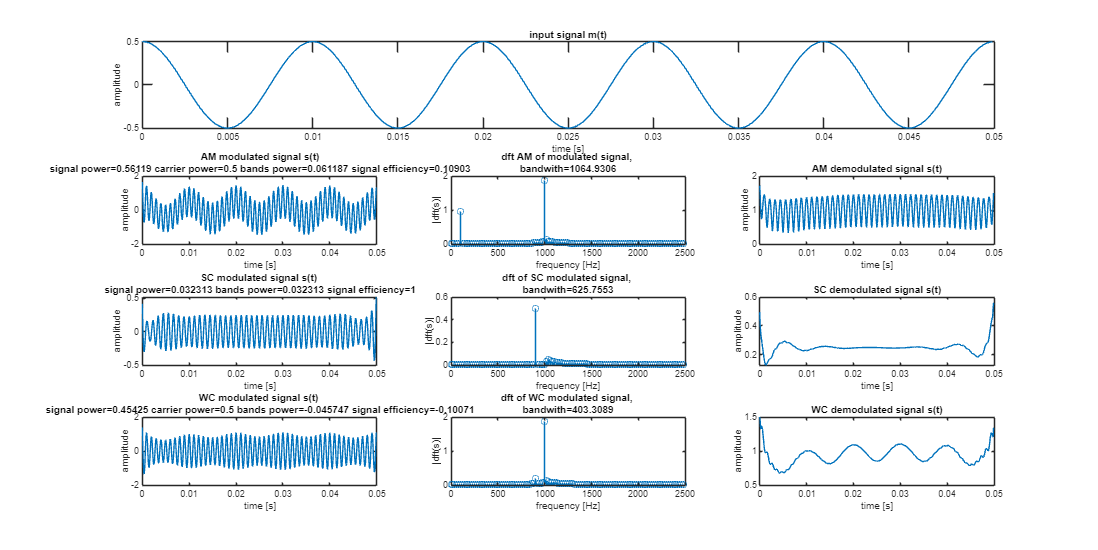

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m1)

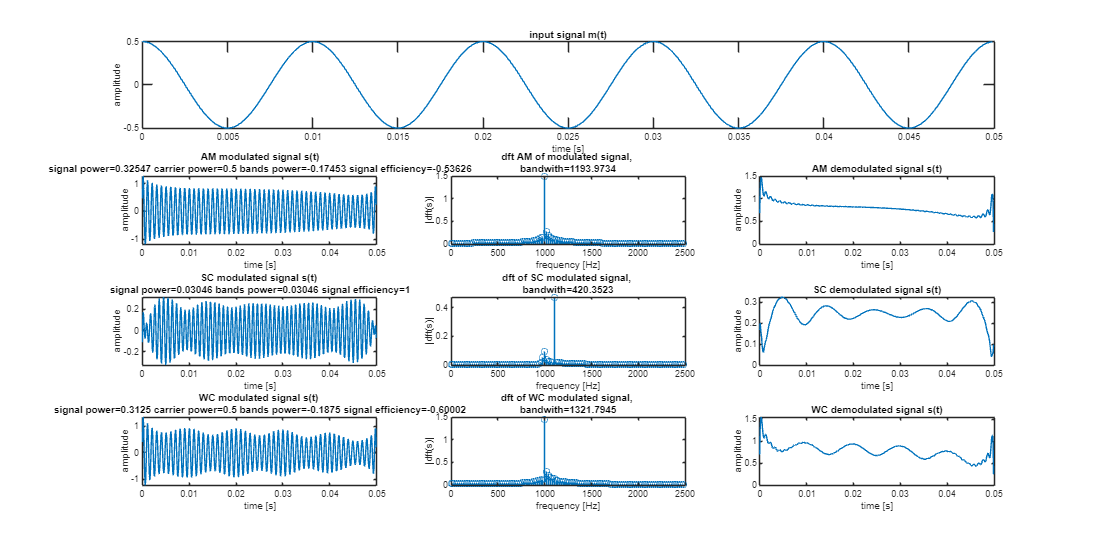

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m1)

#### Obserwacje:

W powyższych symulacjach obserwujemy kolejno obcięcie wstęgi dolnej oraz górnej. Sygnał modulowany za pomocą modulacj WC nadal przypomina sygnał pierwotny.

#### Wnioski:

Możemy zaoszczędzić bandwidth poprzez wycięcie jednej wstęgi bocznej kosztem spadku jakości odbieranego sygnału. Jeżeli jest on dostatecznie dobrej jakości nadal możliwe będzie poprawne zdekodowanie.

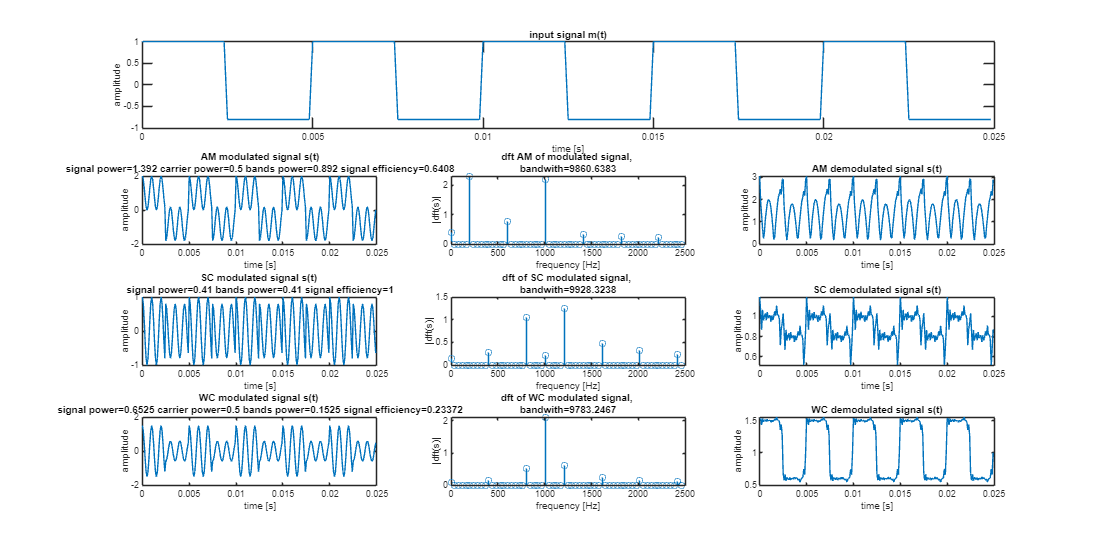


%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.5;
fm = 200;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m2-----------------------------

one_cycle = [ones(1, length(t)/10), K * ones(1, length(t)/10)];
m2 = [one_cycle, one_cycle, one_cycle, one_cycle, one_cycle];

calculate(c, fs, Am, Ac, t, m2)

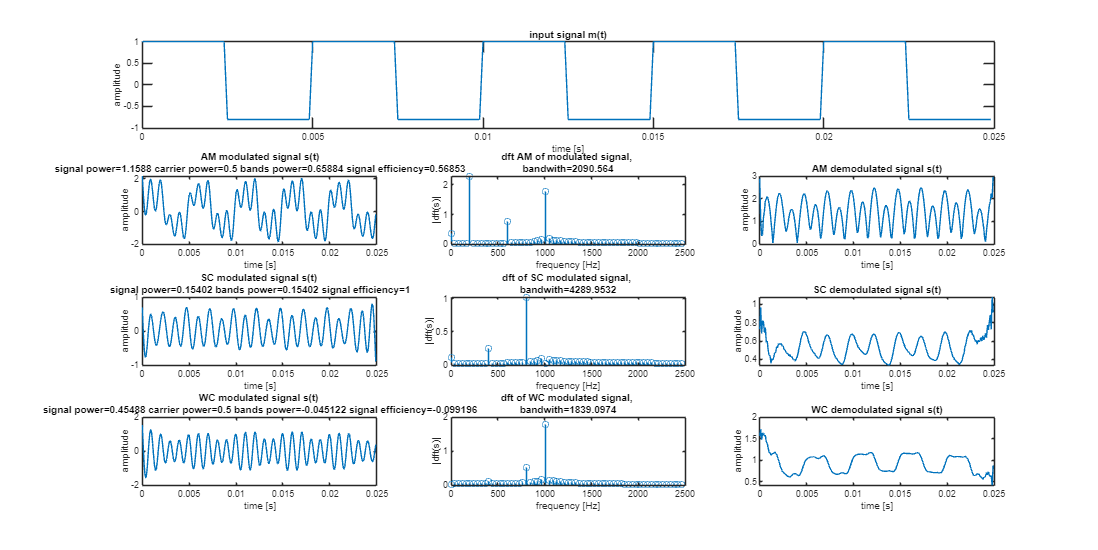

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m2)

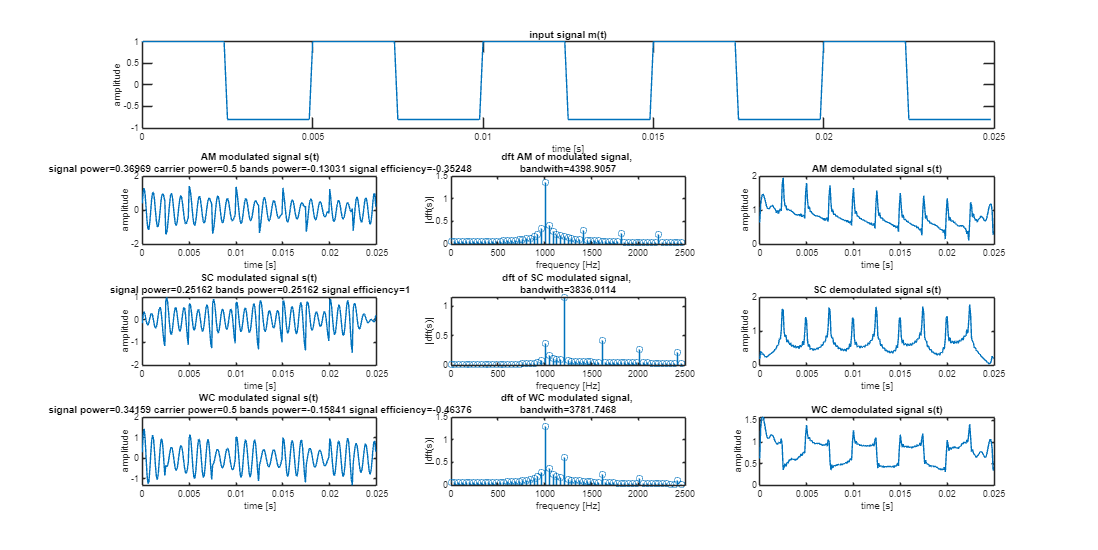

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m2)

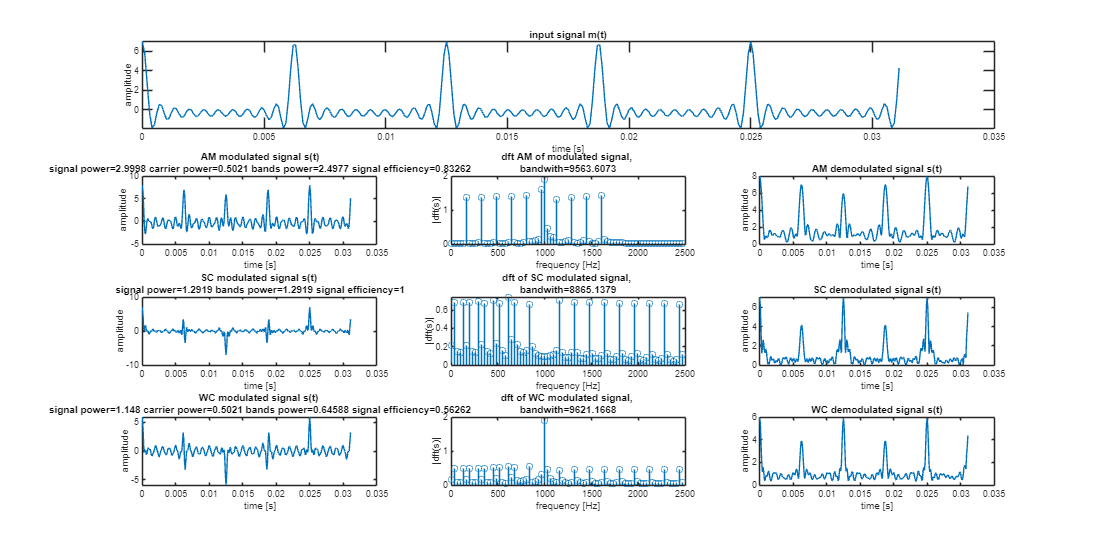



%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.7;
fm = 160;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m3-----------------------------
m3 = 0;
for i = 1:10
    m3 = m3 + Am * cos(2*pi*fm*i*t);
end

calculate(c, fs, Am, Ac, t, m3)

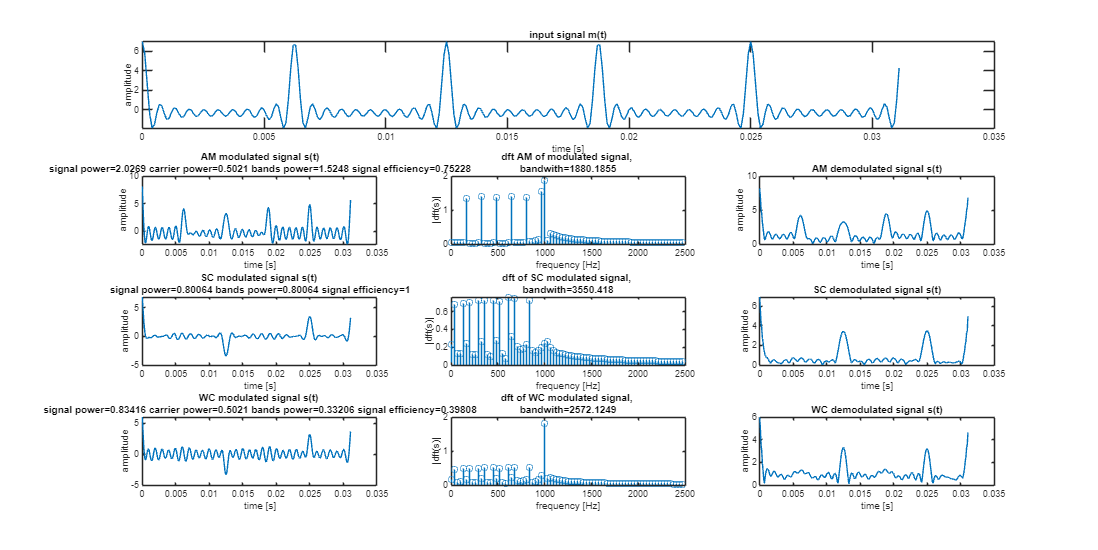

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m3)

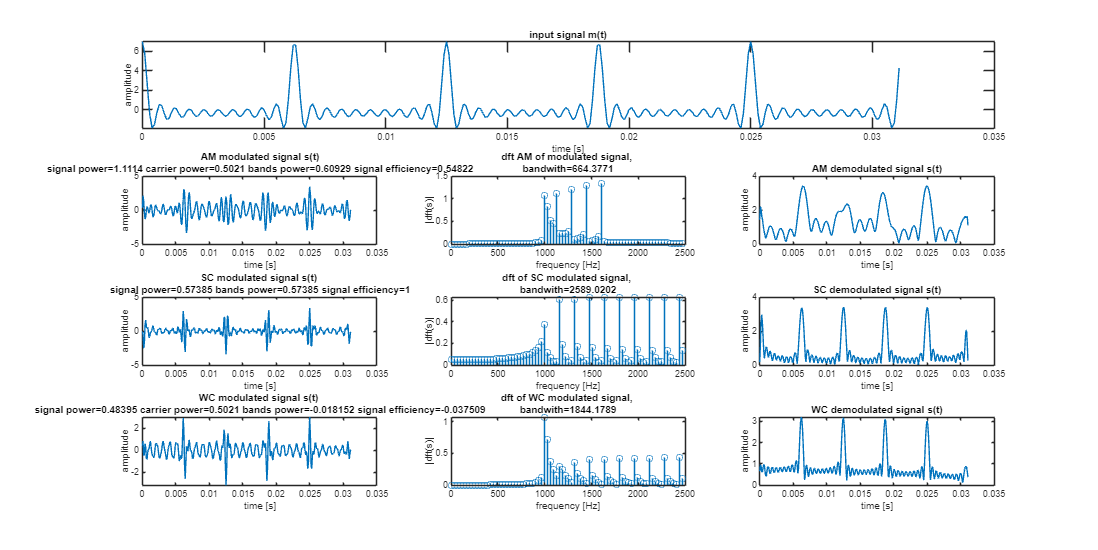

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m3)

function X = calculate(c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;
    dB1 = 18;

    s1_m1 = c + m1;
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1_fft, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1_fft, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1_fft, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end



function X = calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;

    s1_m1 = c + m1;
    s1_m1 = lowpass(s1_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1 = lowpass(s2_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1 = lowpass(s3_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end


function X = calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;

    s1_m1 = c + m1;
    s1_m1 = highpass(s1_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1 = highpass(s2_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1 = highpass(s3_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end

